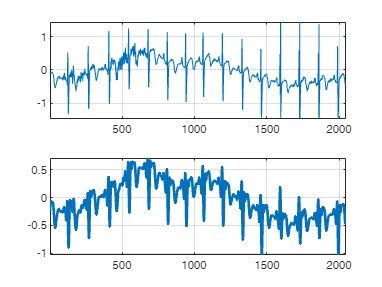

[data,annotations] = edfread("H:/181022/Аня_filtered.edf");
info = edfinfo("H:/181022/Аня_filtered.edf");
fs = info.NumSamples/seconds(info.DataRecordDuration);
ecg=data(:,3);
%plot(ecg);
fs2=fs(3);
load wecg
wt = tqwt(wecg,QualityFactor=2,Level=6);
mra = tqwtmra(wt,length(wecg),QualityFactor=2);
figure();
subplot(2,1,1);
plot(wecg);
axis tight;

grid("on");
subplot(2,1,2);
plot(mra(end,:),linewidth=2);
axis tight;

grid("on");

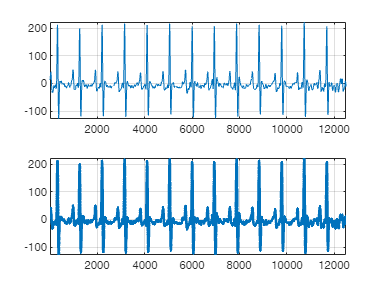

mraSum = sum(mra,1);
max(abs(mraSum(:)-wecg(:)));
[y,Fs] = audioread("C:/Users/Евгений/PycharmProjects/pythonProject/source/Фильтрованные/4/НЧ/2.wav");
wt = tqwt(y(62500:75000),QualityFactor=2,Level=6);
mra = tqwtmra(wt,length(y(62500:75000)),QualityFactor=2);
figure();
subplot(2,1,1);
plot(y(62500:75000));
axis tight;
grid("on");
axis tight;
subplot(2,1,2);
plot(mra(7,:),linewidth=2);
axis tight;
grid("on");